clc
clear
A = [125 25 5 1 ;216 36 6 1 ;512 64 8 1;1728 144 12 1];
B = [106.8 ;129.6; 177.2 ;279.2];
Answer = gauss(A,B);
syms t V(t);
V(t) = 0;
n = length(B);
for i = 1 : n
    V(t) = V(t) + Answer(i)*t^(n-i);
end
fprintf('V1 = %d',vpa(V(10)));

V1 = 227

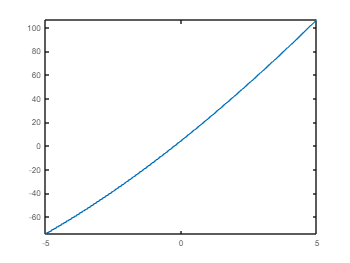

fplot (V(t));



answer = jacobi(A,B,20);
n = length(B);
syms t V(t);
V(t) = 0;
for i = 1 : n
    V(t) = V(t) + answer(i)*t^(n-i);
end
fprintf('V2 = %d',vpa(V(10)));

V2 = -292221158020092439

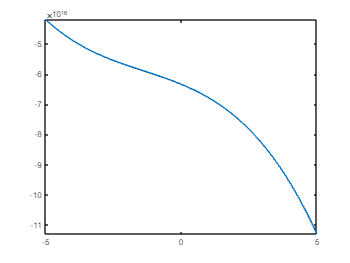

fplot (V(t));



A = [5 6 8 12];
B = [106.8 129.6 177.2 279.2];
syms x V(x);
V(x)=lagrange(A,B);
fprintf('V3 = %d',vpa(V(10)));

V3 = 227

fplot(V(x));

function output = gauss(A,B)
n = length(B);
AOB = [A B];
Answer = zeros(n,1);
for i = 1 : n
    for j = i+1 : n
        ratio = AOB(j,i) / AOB(i,i);
        AOB(j,:) = AOB(j,:) - ratio*AOB(i,:);
    end
end
for i = 1 : n
    B(i) = AOB(i,n+1);
end
for i = n : -1 : 1
    Answer(i) = B(i);
    for j = i+1 : n
        Answer(i) = Answer(i) - AOB(i,j)*Answer(j);
    end
    Answer(i) = Answer(i)/AOB(i,i);
end
output = Answer;
end
% -----------
function output = jacobi(A,B,iteration)
n = length(B);
x = zeros(n,1);
x_new = zeros(n,1);
for i = 1 : iteration
    for j = 1 : n
        x_new(j) = (B(j)-A(j,[1:j-1,j+1:n])*x([1:j-1,j+1:n],1))/A(j,j);
    end
    x = x_new;
end
output = x_new;
end
% -----------
function [out] = lagrange(A,B)
n = length(A);
syms x V(x);
V(x) = 0;
for i = 1 : n
    L = 1;
    for j = 1 : n
        if j~=i
            L = L*(x-A(j))/(A(i)-A(j));
        end
    end
    V(x) = V(x) + L*B(i);
out = V(x);
end
end